## Part A

### 1)

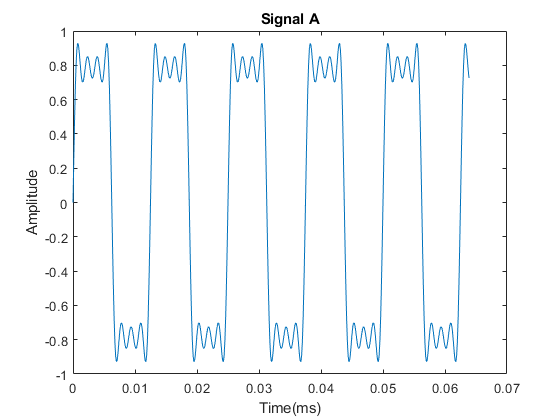

fs = 8000;
n = 512;

%Signal A
[s80t, s80] = Sinusoid(80,1,fs,n,1,0,0);
[s240t, s240] = Sinusoid(240,0.3333,fs,n,1,0,0);
[s400t, s400] = Sinusoid(400,0.2,fs,n,1,0,0);
[s560t, s560] = Sinusoid(560,0.1429,fs,n,1,0,0);

SignalA = LinCombo(s80, 1, s240, 1, s400, 1, s560, 1);

plot(s80t, SignalA);
title 'Signal A';
xlabel 'Time(ms)';
ylabel 'Amplitude';

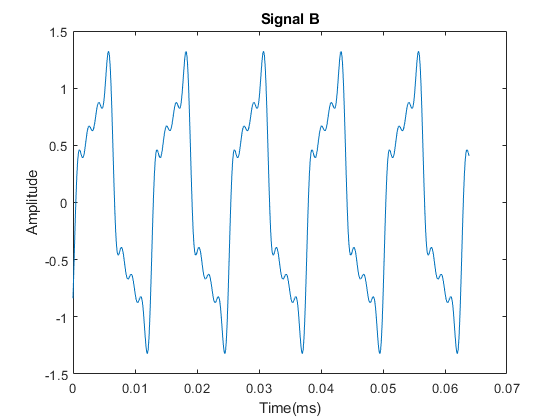


%Signal B
[s80t, s80] = Sinusoid(80,1,fs,n,1,0,-30);
[s240t, s240] = Sinusoid(240,0.3333,fs,n,1,0,-30);
[s400t, s400] = Sinusoid(400,0.2,fs,n,1,0,-30);
[s560t, s560] = Sinusoid(560,0.1429,fs,n,1,0,-30);

SignalB = LinCombo(s80, 1, s240, 1, s400, 1, s560, 1);

plot(s80t, SignalB);
title 'Signal B';
xlabel 'Time(ms)';
ylabel 'Amplitude';

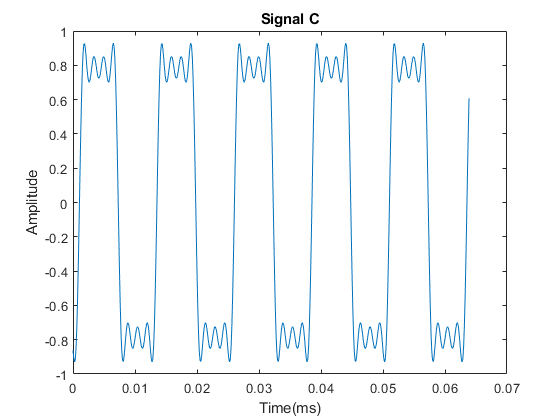


%Signal C
[s80t, s80] = Sinusoid(80,1,fs,n,1,0,-30);
[s240t, s240] = Sinusoid(240,0.3333,fs,n,1,0,-90);
[s400t, s400] = Sinusoid(400,0.2,fs,n,1,0,-150);
[s560t, s560] = Sinusoid(560,0.1429,fs,n,1,0,-210);

SignalC = LinCombo(s80, 1, s240, 1, s400, 1, s560, 1);

plot(s80t, SignalC);
title 'Signal C';
xlabel 'Time(ms)';
ylabel 'Amplitude';

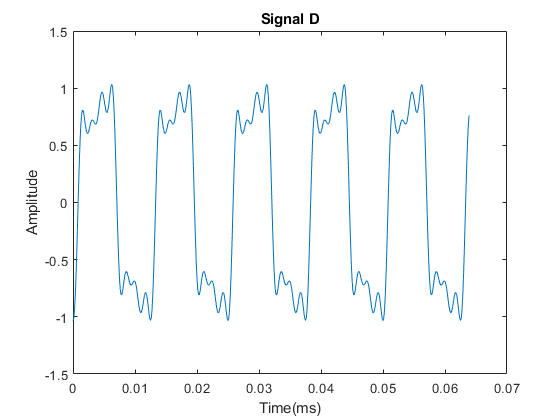


%Signal D
[s80t, s80] = Sinusoid(80,1,fs,n,1,0,-30);
[s240t, s240] = Sinusoid(240,0.3333,fs,n,1,0,-60);
[s400t, s400] = Sinusoid(400,0.2,fs,n,1,0,-120);
[s560t, s560] = Sinusoid(560,0.1429,fs,n,1,0,-150);

SignalD = LinCombo(s80, 1, s240, 1, s400, 1, s560, 1);

plot(s80t, SignalD);
title 'Signal D';
xlabel 'Time(ms)';
ylabel 'Amplitude';

### 2)

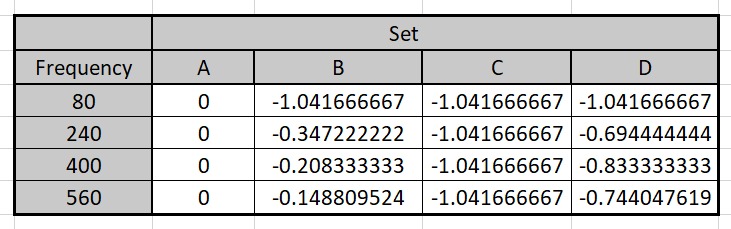

### 3)

The only sets exhibiting linear phase is set C and sert A, since Their the only sets that the time delay remains the same with their changes in frequency. 

## Part B

Tones being used:

4th digit in student number: 9

DTFM tones: 1477Hz and 852Hz

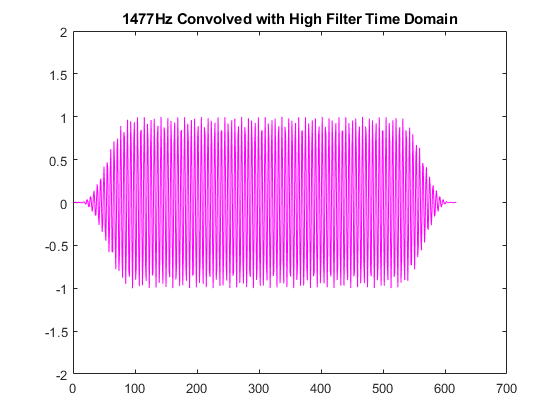

[s1477t, s1477] = Sinusoid(1477,1,fs,n,1,0,0);
[s852t, s852] = Sinusoid(852,1,fs,n,1,0,0);
Combined = LinCombo(s1477,1,s852,1,0,0,0,0);

%low tone
FFT = (fft(s852));          % FFt calculated
P2 = abs(FFT/n);
P1 = P2(1:n/2+1);

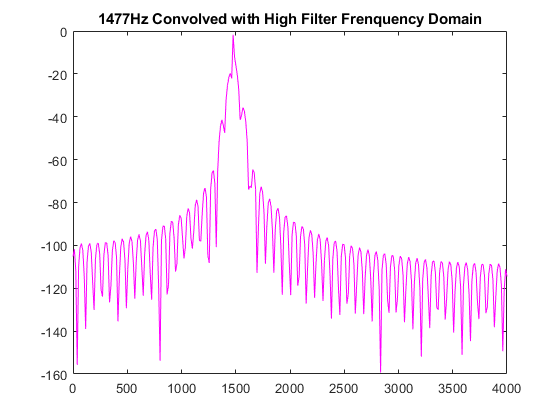

P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = fs*(0:(n/2))/n;
plot(fD, dB, 'r');
title 'FFT of Lower DTFM Tone';

%high tone
FFT = (fft(s1477));          % FFt calculated
P2 = abs(FFT/n);
P1 = P2(1:n/2+1);

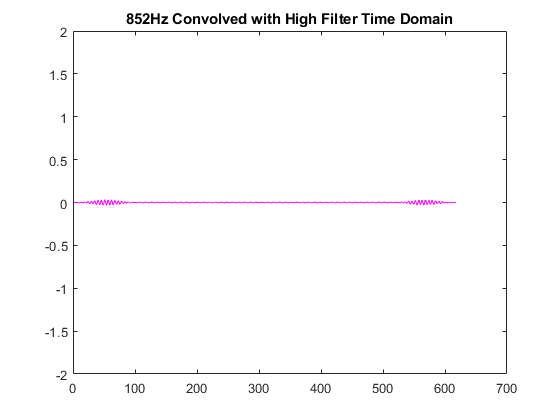

P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = fs*(0:(n/2))/n;
plot(fD, dB, 'r');
title 'FFT of Higher DTFM Tone';

%combined DTFM tone

FFT = (fft(Combined));          % FFt calculated
P2 = abs(FFT/n);
P1 = P2(1:n/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = fs*(0:(n/2))/n;
plot(fD, dB,'r');
title 'FFT of Combined DTFM Tone';

High Tone Filter Set Up:

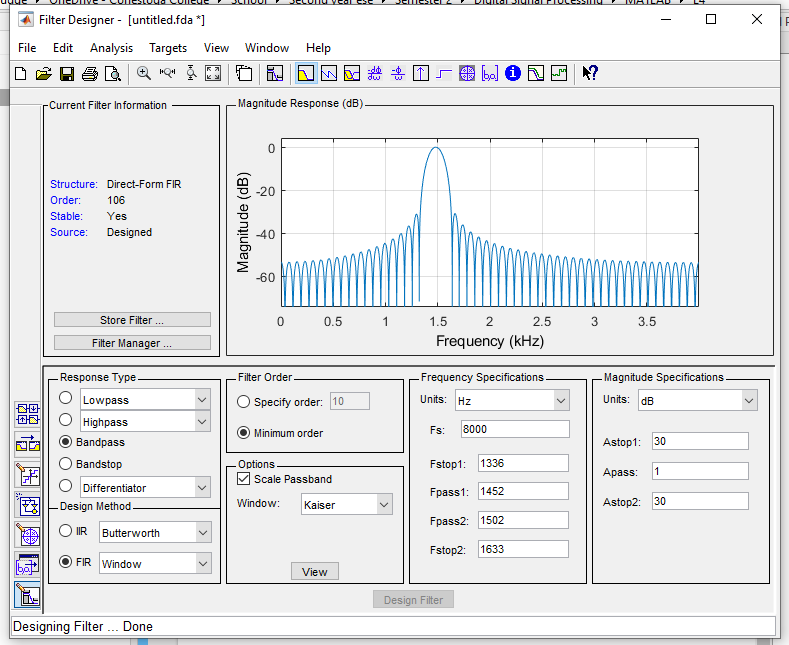

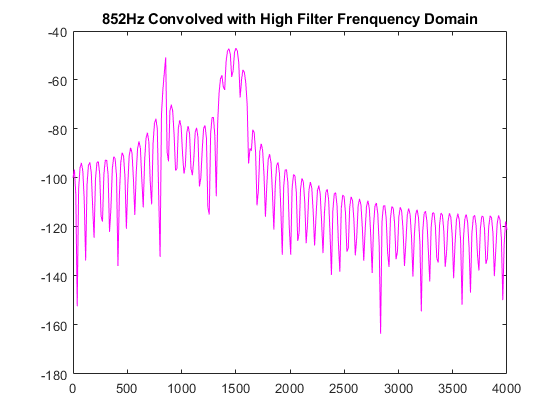

%high side
%letting through DTFM high tone

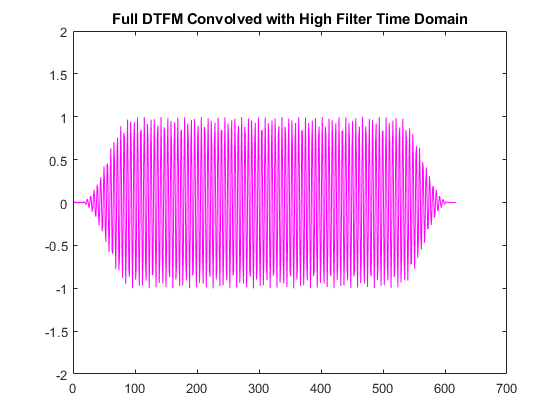

Hhigh = conv(HighFIR, s1477);

plot(Hhigh,'m');
ylim([-2,2]);
title '1477Hz Convolved with High Filter Time Domain';

N = 618;

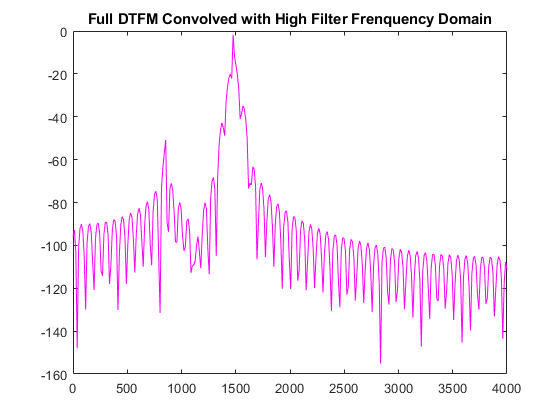

FFT = (fft(Hhigh));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = fs*(0:(N/2))/N;
plot(fD, dB, 'm');
title '1477Hz Convolved with High Filter Frenquency Domain';

%blocking DTFM low tone

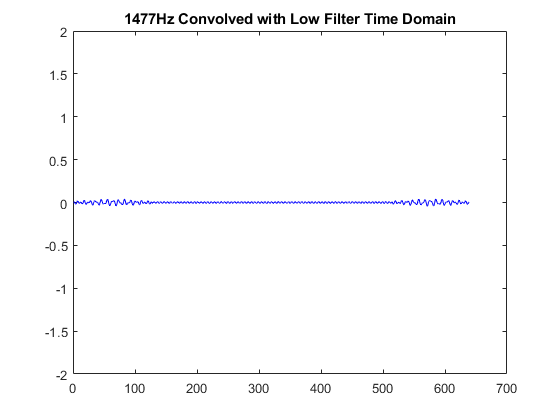

Hlow = conv(HighFIR, s852);

plot(Hlow, 'm');
ylim([-2,2]);
title '852Hz Convolved with High Filter Time Domain';

N = 618;
FFT = (fft(Hlow));          % FFt calculated
P2 = abs(FFT/N);

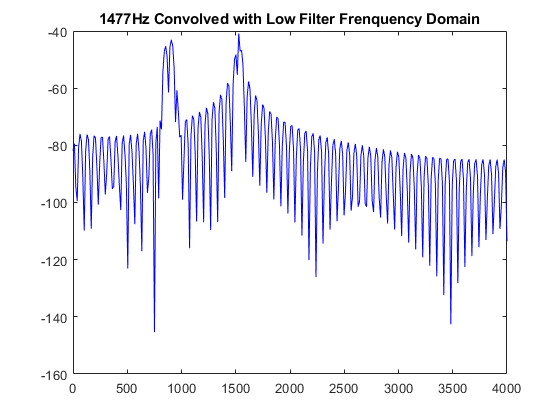

P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = fs*(0:(N/2))/N;
plot(fD, dB, 'm');
title '852Hz Convolved with High Filter Frenquency Domain';

%blocking DTFM low tone and passing DTFM high tone
Hboth = conv(HighFIR, Combined);


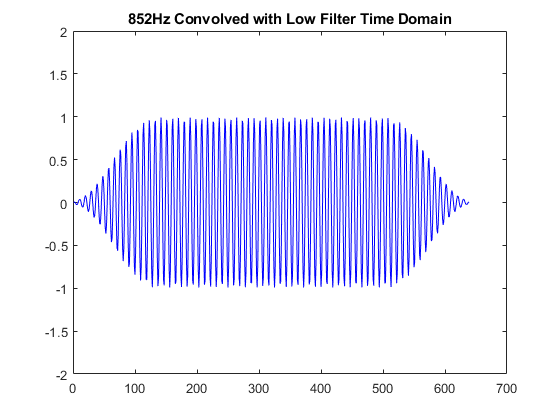

plot(Hboth, 'm');
ylim([-2,2]);
title 'Full DTFM Convolved with High Filter Time Domain';

N = 618;
FFT = (fft(Hboth));          % FFt calculated
P2 = abs(FFT/N);

P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = fs*(0:(N/2))/N;
plot(fD, dB, 'm');
title 'Full DTFM Convolved with High Filter Frenquency Domain'

Low Tone Filter Set Up

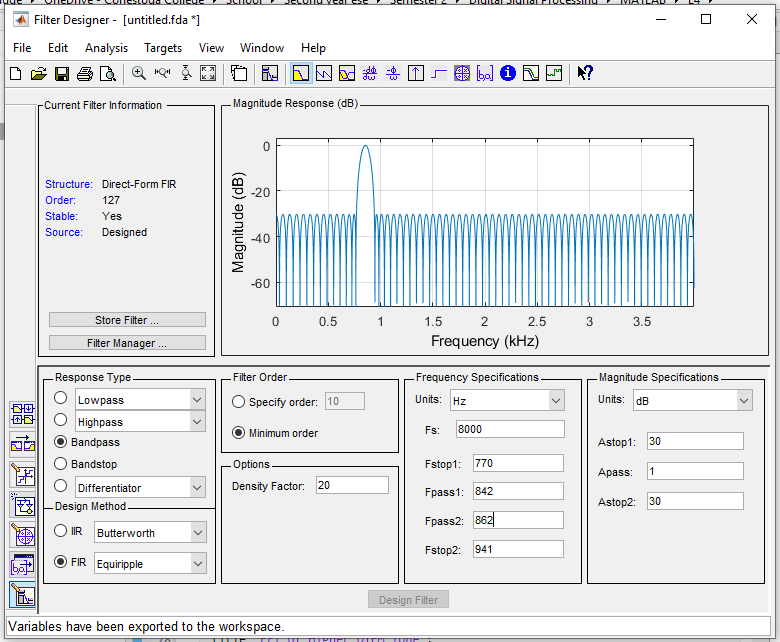

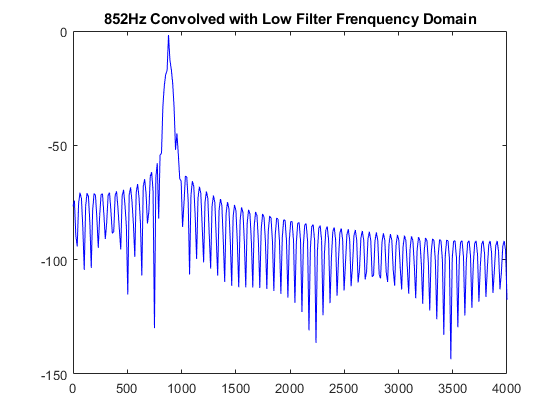

%low side
%Blocking DTFM high tone
Lhigh = conv(LowFIR, s1477);


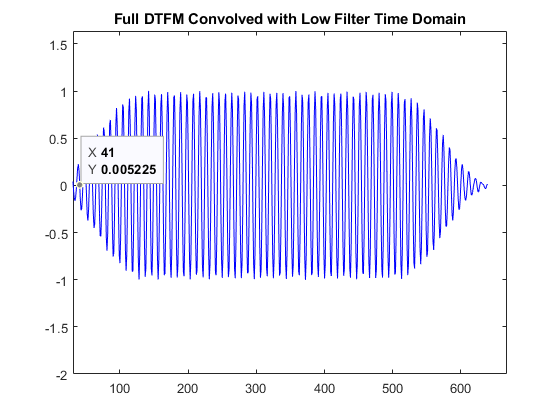

plot(Lhigh,'b');
ylim([-2,2]);
title '1477Hz Convolved with Low Filter Time Domain';

N = 618;
FFT = (fft(Lhigh));          % FFt calculated
P2 = abs(FFT/N);

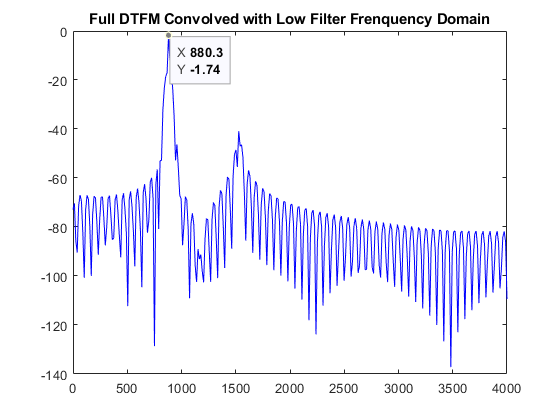

P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = fs*(0:(N/2))/N;
plot(fD, dB, 'b');
title '1477Hz Convolved with Low Filter Frenquency Domain';

%letting thorugh DTFM low tone
Llow = conv(LowFIR, s852);


plot(Llow, 'b');
ylim([-2,2]);
title '852Hz Convolved with Low Filter Time Domain';

N = 618;
FFT = (fft(Llow));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = fs*(0:(N/2))/N;
plot(fD, dB, 'b');
title '852Hz Convolved with Low Filter Frenquency Domain';

%blocking DTFM high tone and passing DTFM low tone
LBoth = conv(LowFIR, Combined);

plot(LBoth, 'b');
ylim([-2,2]);
title 'Full DTFM Convolved with Low Filter Time Domain';

N = 618;
FFT = (fft(LBoth));          % FFt calculated
P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1); 
dB = 20*log10(P1);              % Convert to dB
fD = fs*(0:(N/2))/N;
plot(fD, dB, 'b');
title 'Full DTFM Convolved with Low Filter Frenquency Domain';